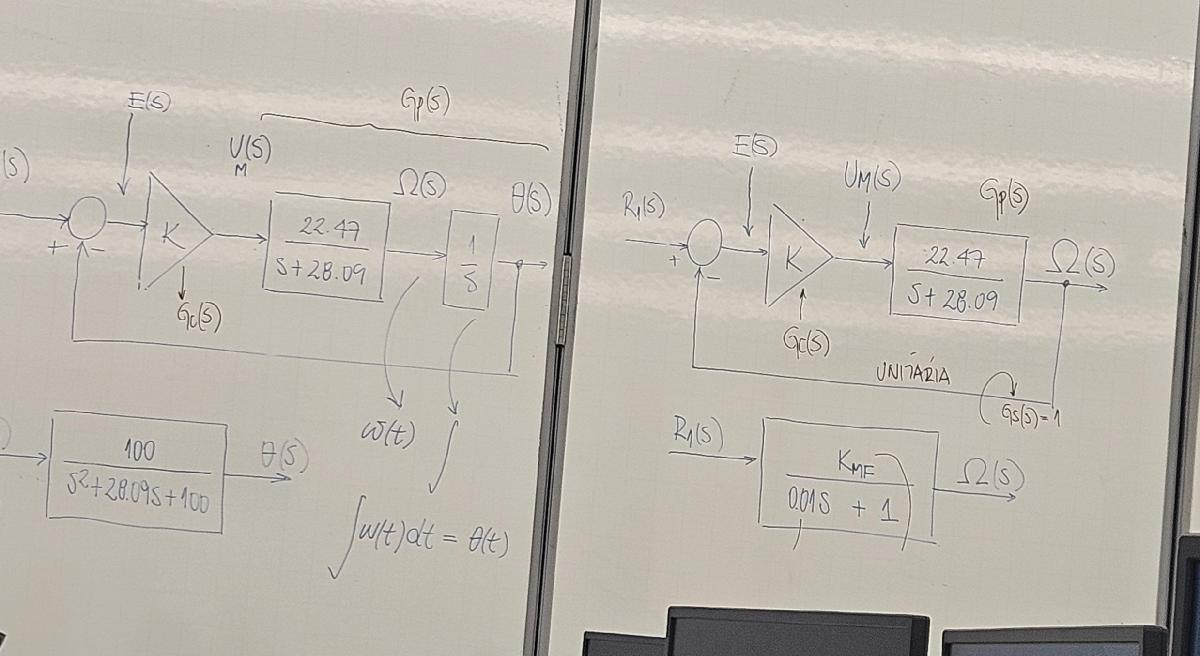

entrada = ent.signals.values; %% degrau
velocidade = vel.signals.values; %% exponencial

%%% definindo tempo %%%
Np = length(entrada); 
Ts = 2/1000;
tempo = 0 : Ts : (Np-1)*Ts;

%%% ajuste de parametros %%%

x0 = [1 1]; %% condição inicial

X = fminsearch(@(x) ErroQuadratico(x, entrada, velocidade, tempo'), x0)

X =   132.1691    5.7970


%%% verificando resultado %%%

Km = X(1);
pm = X(2);

Gp = tf(Km, [1 pm]) %% função transferencia do modelo


Gp =
 
    132.2
  ---------
  s + 5.797
 
Continuous-time transfer function.




ym = lsim(Gp, entrada, tempo); %% saida do modelo para a mesma entrada

Gcontrol = tf(1, [1 0.5 0])


Gcontrol =
 
       1
  -----------
  s^2 + 0.5 s
 
Continuous-time transfer function.




Gmalha = Gcontrol * Gp


Gmalha =
 
            132.2
  -------------------------
  s^3 + 6.297 s^2 + 2.898 s
 
Continuous-time transfer function.



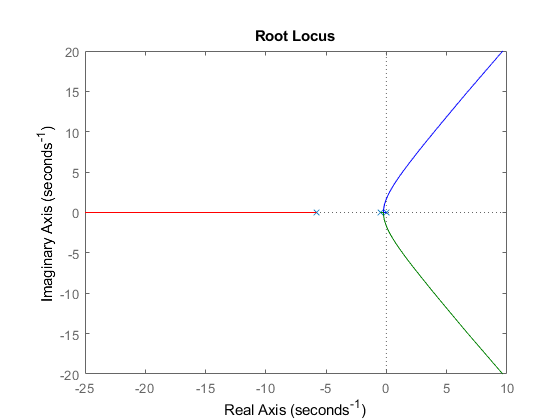


rlocus(Gmalha)

function [Eq] = ErroQuadratico(X,u,y,t)
% Esta função determina o erro quadrático
% entre a saída real e a saída do modelo.
% u - entrada real
% y - saída real
% t - tempo real
% X = [Km pm];

Km= X(1);
pm = X(2);

%%% Modelo

Gp = tf(Km, [1 pm]);

%%% Saida do modelo

ym = lsim(Gp, u, t);

%%% Erro quadrático

Eq = sum((y-ym).^2); %% cálculo do erro

% plot(t,y,t,ym,"linewidth", 2)

end
